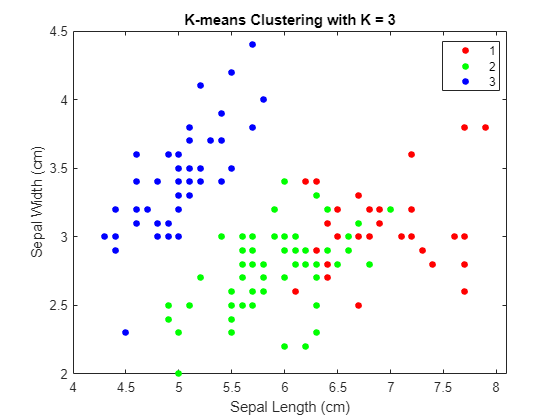

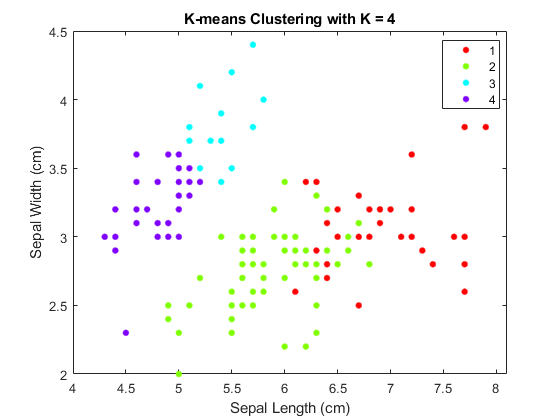

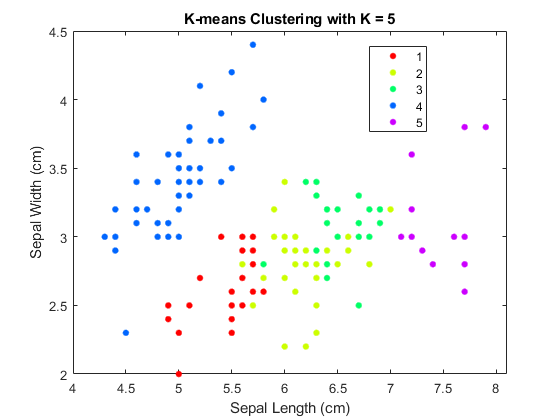

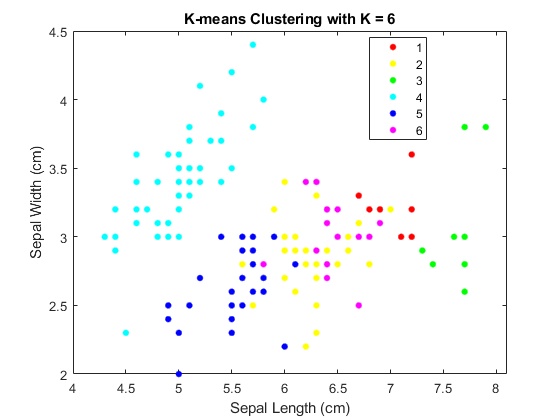

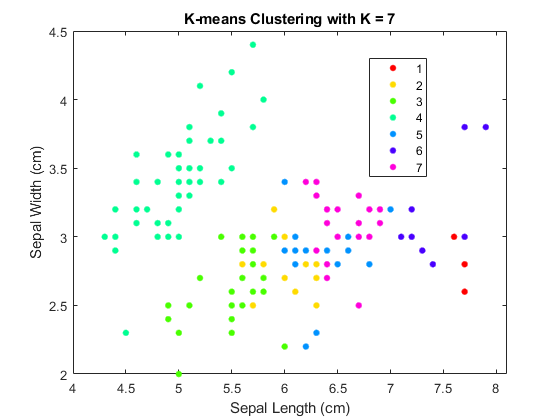

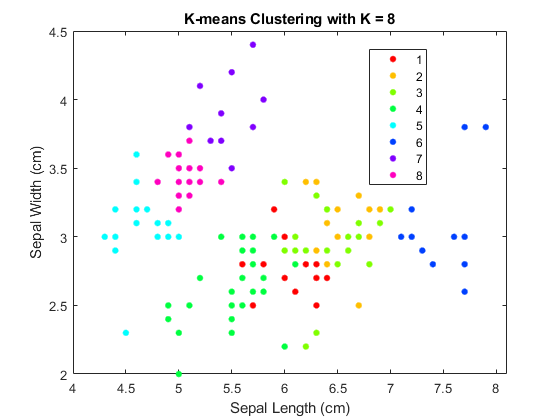

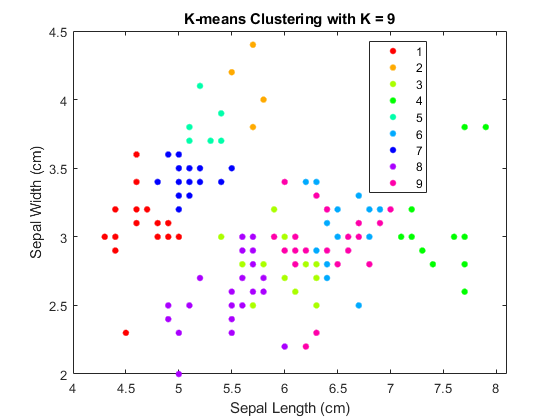

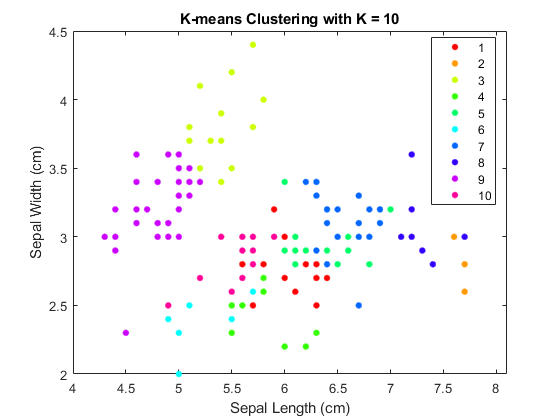

% Load the Iris dataset
load fisheriris

% Extract the features and true labels
X = meas;
% X = zscore(X);

true_labels = grp2idx(species);  % true class labels (N x 1)
percentageCell = {'Number of Clusters' 'Accuracy'};
% K = number of clsuters
K = 3;
while K <= 100%increment the number of clusters
% pick K number of random points
centroids = X(randperm(size(X, 1), K), :);

% max iterations
max_iters = 100;


% init labels
labels = zeros(size(X, 1), 1);


% k mean algo 
for iter = 1:max_iters
    % assign each point to closest cluster
    distances = pdist2(X,centroids);
    [~,labels] = min(distances,[],2);
    
    %update centroids
    for k = 1:K
        centroids(k,:) = mean(X(labels==k,:),1);
    end
    
 
    
end

% Compute accuracy
acc = 0;
for k = 1:K
    idx = (labels == k);
    
    modes = mode(true_labels(idx));
    correct = sum(true_labels(idx) == modes);
    acc = acc + correct;
end

% compute mean percentage of elements in each cluster
percentages = zeros(K, 1);
for k = 1:K
    percentages(k) = sum(labels == k) / length(labels);
end

% calculate element in cluster distribution rate
ecr = sum(percentages.^2);

accuracy = acc/length(labels);
percentageCell{end+1, 1} = K;
percentageCell{end,2} = accuracy;
percentageCell{end,3} = ecr;

mean_percentage = mean(percentages);
 figure(K)
 gscatter(X(:,1),X(:,2),labels)
 xlabel('Sepal Length (cm)')
 ylabel('Sepal Width (cm)')
 str1 = 'K-means Clustering with K = ';
 str2 = num2str(K);
 title1 = append(str1,str2);
 title(title1);
% line([-2 3], [mean_percentage mean_percentage], 'Color', 'red', 'LineWidth', 2);
K = K + 1;

end


Xaxis = [percentageCell{2:end, 1}]

Xaxis =      3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50    51    52


Yaxis = [percentageCell{2:end, 2}]

Yaxis =     0.8933    0.8867    0.9067    0.9067    0.9667    0.9733    0.9533    0.9733    0.9867    0.9067    0.9733    0.9733    0.9800    0.9467    0.9467    0.9533    0.9800    0.9600    0.9733    0.9667    0.9600    0.9800    0.9800    0.9800    0.9667    0.9667    0.9533    0.9733    0.9533    0.9800    0.9733    0.9733    0.9733    0.9667    0.9867    0.9733    0.9600    0.9600    0.9667    0.9800    0.9667    0.9733    0.9800    0.9800    0.9733    0.9733    0.9733    0.9733    0.9867    0.9800


X2axis = [percentageCell{2:end, 3}]

X2axis =     0.3461    0.2942    0.2356    0.2246    0.2032    0.1329    0.1273    0.1284    0.1241    0.1085    0.1016    0.0965    0.0929    0.0780    0.0829    0.0769    0.0792    0.0684    0.0658    0.0525    0.0532    0.0597    0.0555    0.0473    0.0446    0.0493    0.0425    0.0456    0.0412    0.0474    0.0401    0.0405    0.0378    0.0378    0.0507    0.0339    0.0349    0.0329    0.0310    0.0322    0.0343    0.0316    0.0330    0.0299    0.0276    0.0276    0.0288    0.0258    0.0320    0.0269


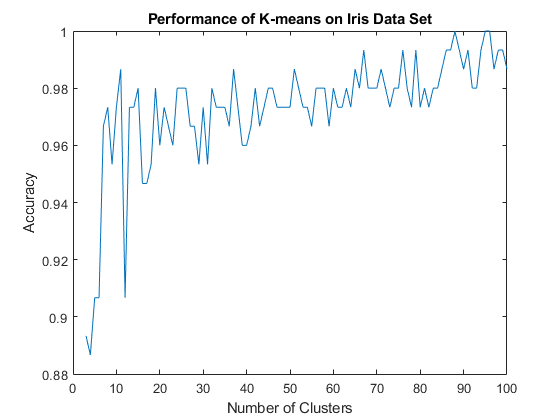

figure(1);
plot(Xaxis, Yaxis);

title('Performance of K-means on Iris Data Set')
xlabel('Number of Clusters');
ylabel('Accuracy');

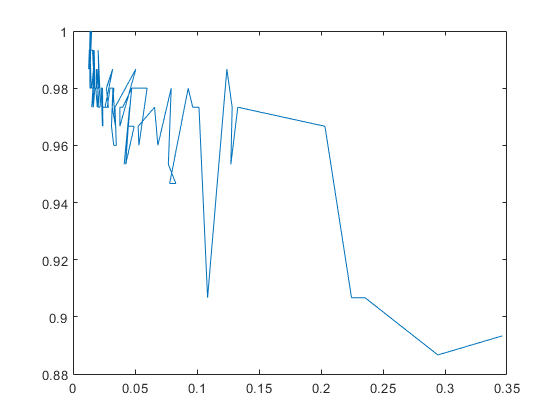

figure(2);
plot(X2axis,Yaxis);